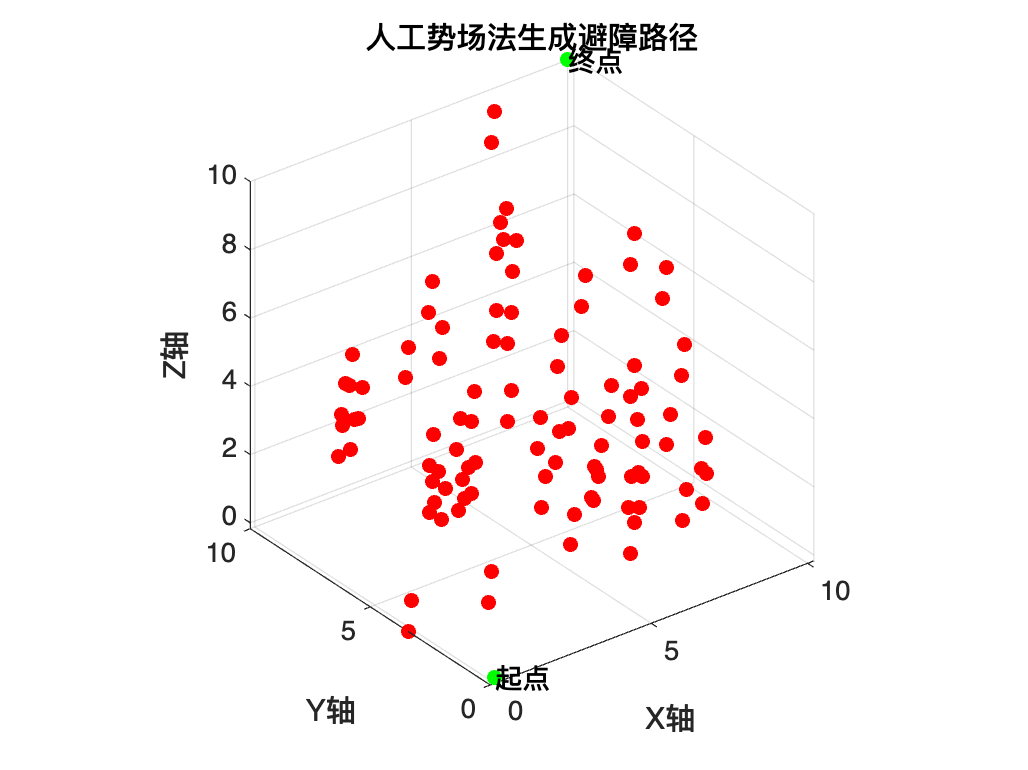

clc;
close all;
clear;

% 障碍物数量
num = 10;  

% 随机生成 X、Y、Z 坐标和大小
obstacle_size = 0.5;  % 障碍物大小（方块边长）
obstacle_positions = rand(num, 3) * 10;
obstacle = [
    obstacle_positions - obstacle_size / 2,   % 左下角坐标
    obstacle_positions + obstacle_size / 2    % 右上角坐标
];

% 创建初始位置和目标位置
start = [0 0 0];
goal = [10 10 10];

% 生成并绘制避障路径
path = APF3D(start, goal, obstacle);

% 绘制地图
figure();
scatter3(obstacle(:, 1), obstacle(:, 2), obstacle(:, 3), 'r', 'filled');
xlabel('X轴'); ylabel('Y轴'); zlabel('Z轴'); title('人工势场法生成避障路径');
grid on; axis equal;

hold on;
scatter3(start(1), start(2), start(3), 'filled', 'g');
text(start(1), start(2), start(3), '起点');
scatter3(goal(1), goal(2), goal(3), 'filled', 'g');
text(goal(1), goal(2), goal(3), '终点');


% 绘制方块障碍物
for i = 1:num
    drawCube(obstacle(i, :));
end

索引超过数组元素的数量。索引不能超过 3。

出错 drawCube (第 3 行)
    x = [position(1), position(1), position(1) + position(4), position(1) + position(4), position(1)];


% % 绘制避障路径
% plot3(path(:, 1), path(:, 2), path(:, 3), 'LineWidth', 1, 'Color', 'b');
